clearvars

# Wind tunnel model 

u1 : flow control, u2 : temperature control

y1 : flow measure, y2 : temperature measure

## Identified model

% H1: ventilation and flow u1 and y1 
H1 = tf([1.053,1.155],[1,1.942,6.112,1.517],'InputDelay',0.1);

% H2: chauffage and flow u2 and y1
H2 = 0;

% H3: ventilation and temperature u1 and y2
H3 = tf([-0.005487,0.02488,0.0264],[1,0.7964,0.1684],'InputDelay',1.7);

% H4: chauffage and temperature u2 and y2
H4 = tf([1.347,0.8525],[1,5.102,9.509,3.071],'InputDelay',0.05);

H = [H1, H2;H3, H4];

# Control model (discrete state space)

choice of a sampling period (keep the notation Te)

Te = 0.05;

% Matlab function to discretize a system
Hd = c2d(H,Te);

Change to state form, and state matrices extraction.

sysd=ss(Hd)

sysd =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1   2.893    -1.4  0.9075       0       0       0       0       0
   x2       2       0       0       0       0       0       0       0
   x3       0     0.5       0       0       0       0       0       0
   x4       0       0       0   1.961  -0.961       0       0       0
   x5       0       0       0       1       0       0       0       0
   x6       0       0       0       0       0   2.754  -1.264  0.7748
   x7       0       0       0       0       0       2       0       0
   x8       0       0       0       0       0       0     0.5       0
 
  B = 
           u1      u2
   x1  0.0625       0
   x2       0       0
   x3       0       0
   x4  0.0625       0
   x5       0       0
   x6       0  0.0625
   x7       0       0
   x8       0       0
 
  C = 
               x1          x2          x3          x4          x5          x6          x7          x8
   y1     0.02074   0.0004082    -0.

A=sysd.A

A =     2.8928   -1.4002    0.9075         0         0         0         0         0
    2.0000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0         0    1.9605   -0.9610         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    2.7537   -1.2644    0.7748
         0         0         0         0         0    2.0000         0         0
         0         0         0         0         0         0    0.5000         0


B=sysd.B

B =     0.0625         0
         0         0
         0         0
    0.0625         0
         0         0
         0    0.0625
         0         0
         0         0


C=sysd.C

C =     0.0207    0.0004   -0.0194         0         0         0         0         0
         0         0         0    0.0235   -0.0224    0.0250   -0.0005   -0.0225


D=sysd.D

D =          0         0
   -0.0055         0


#### Inclusion of operating points

Inclusion of operating points : ${u}_0(k+1)=u_{0}(k)
$ et $y_0(k+1)=y_0(k)$ 

Aa= [A, -B, zeros(8,2); zeros(2,8), eye(2,2), zeros(2,2); zeros(2,10), eye(2,2)];
Ba= [B; zeros(2,2); zeros(2,2)];
Ca= [C, zeros(2,2), eye(2,2)];

#### Decomposition according to observability

Obsa=obsv(Aa,Ca);
rank(Obsa);
% rank is 10;

There are xx observable modes 

[AO,BO,CO,TO,k]=obsvf(Aa,Ba,Ca);

$T0$  is the basis change matrix (useful for Simulink later)

We get only the observable part

Ao=AO(3:12,3:12);
Bo=BO(3:12,1:2);
Co=CO(1:2,3:12);

Eigenvalues study

eig(Ao)

ans =    0.8868 + 0.0643i
   0.8868 - 0.0643i
   0.9803 + 0.0049i
   0.9803 - 0.0049i
   0.9800 + 0.0000i
   0.9531 + 0.1066i
   0.9531 - 0.1066i
   0.9867 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i


## State observer

Choice of the poles:

% poles_obs= eig(Ao);
% pole_obs = exp(Te*)
% poles_obs=[exp(-5*Te);exp(-15*Te);exp(-25*Te);exp(-35*Te);exp(-45*Te);exp(-55*Te);exp(-65*Te);exp(-75*Te);exp(-85*Te);exp(-95*Te)];

Matrice determination

L0 = place(Ao',Co',poles_obs);
L0 = L0';
eig(Ao-L0*Co);

State model of the observer (keep the following notations for simulink)

A_OBS= Ao - L0*Co;
B_OBS= [Bo, L0];
C_OBS= eye(rank(Obsa));
D_OBS= zeros(rank(Obsa), 4);

# Prediction model

Choice of the size of the prediction model

Np=50; % keep the notation Np (required for simulink)

Explicite matrices definition

We want the following model $Y(K+1|k)=Fx(k|k)+HU(K|k)$ 

nx=size(Co*Ao,1); 
% the row number
nc=size(Ao,1);
nu=size(Co*Bo,2);

F=zeros(Np*nx,nc);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=Co*(Ao^i) ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=Co*(Ao^(i-j))*Bo;
    end
end

Unitary tests

% 

# Problem construction: energy minimization, under maximum power constraint.

#### Initial conditions:

y1min = 0;
y1max = 10000;
y2min = 0.1; 
y2max = y2min + 2;
Ymin = repmat([y1min;y2min],Np,1);
Ymax = repmat(y2max,Np,1);

UTOTmax = 20*ones(Np,1);

Nsimu=100;
% u1:flow control; 
% u2:temperature control 

#### Cost function:

1/2 (Y - Ymin)^T (Y - Ymin) + lamda/2 U^T U 

#### Constraints :

lambda_u = 1;
lambda_e = 10000;
W = [eye(2*Np), zeros(2*Np,5*Np); zeros(2*Np), lambda_u*eye(2*Np), zeros(2*Np,3*Np); zeros(3*Np,4*Np), lambda_e*eye(3*Np)];
f = [-Ymin', zeros(1,5*Np)];

T = zeros(Np,2*Np);
for i = 1:Np
    T(i,2*i-1:2*i) = [1,1];
end

P = zeros(Np,2*Np);
for i = 1:Np
    P(i,2*i) = 1;
end

Q = zeros(2*Np,3*Np);
for i = 1:Np
    Q(2*i-1,3*i-2) = 1;
    Q(2*i,3*i-1) = 1;
end

R = zeros(Np,3*Np);
for i = 1:Np
    R(i,3*i) = 1;
end

A_quad = [zeros(Np,2*Np), T, zeros(Np,3*Np); -eye(2*Np), zeros(2*Np), -Q; P, zeros(Np,2*Np), -R];
b_quad = [UTOTmax; -Ymin; P*Ymin + 2*ones(Np,1)];

Aeq = [eye(2*Np), -H, zeros(2*Np,3*Np)];

#### Optimisation problem resolution

#### open loop model validation

xinit=0*ones(10,1);
xk=xinit;
X = [];
U = [];

for i=1:Nsimu
    X = [X xk];
    beq = F*xk;
    [Uopt] = quadprog(W,f,A_quad,b_quad,Aeq,beq,[],[]);
    uk=Uopt(2*Np+1:2*Np+2,1); %optimal control U
    U = [U,uk];
    xkp1=Ao*xk+Bo*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

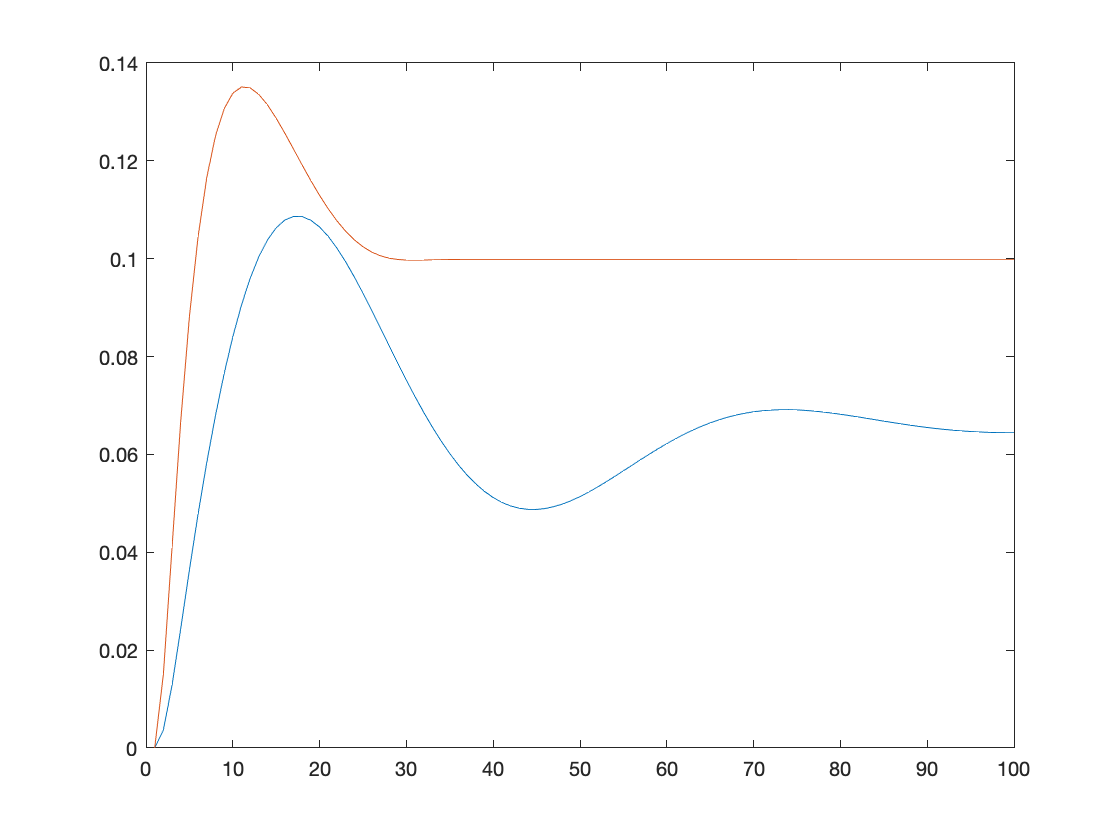

Y_obs = Co*X;
plot(1:Nsimu,Y_obs)

U_tot = U(1,:)+U(2,:)

U_tot =     9.7929    4.7590    1.8387    0.5232    0.1747    0.1861    0.1984    0.2117    0.2259    0.2410    0.2570    0.2738    0.2915    0.3098    0.3288    0.3484    0.3683    0.3884    0.4084    0.4281    0.4471    0.4648    0.4809    0.4945    0.5050    0.5114    0.5128    0.5078    0.4958    0.4814    0.4688    0.4592    0.4528    0.4486    0.4460    0.4441    0.4426    0.4412    0.4398    0.4383    0.4367    0.4351    0.4335    0.4319    0.4303    0.4288    0.4274    0.4260    0.4247    0.4234


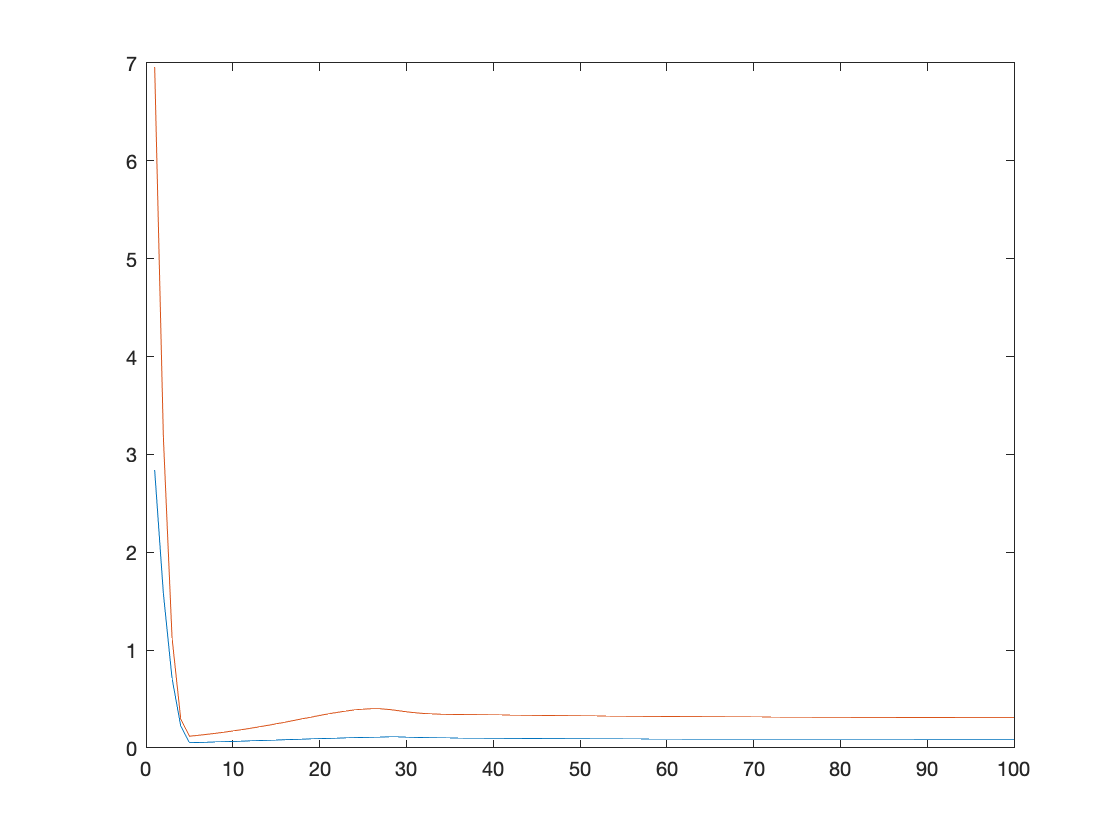

plot(1:Nsimu,U)

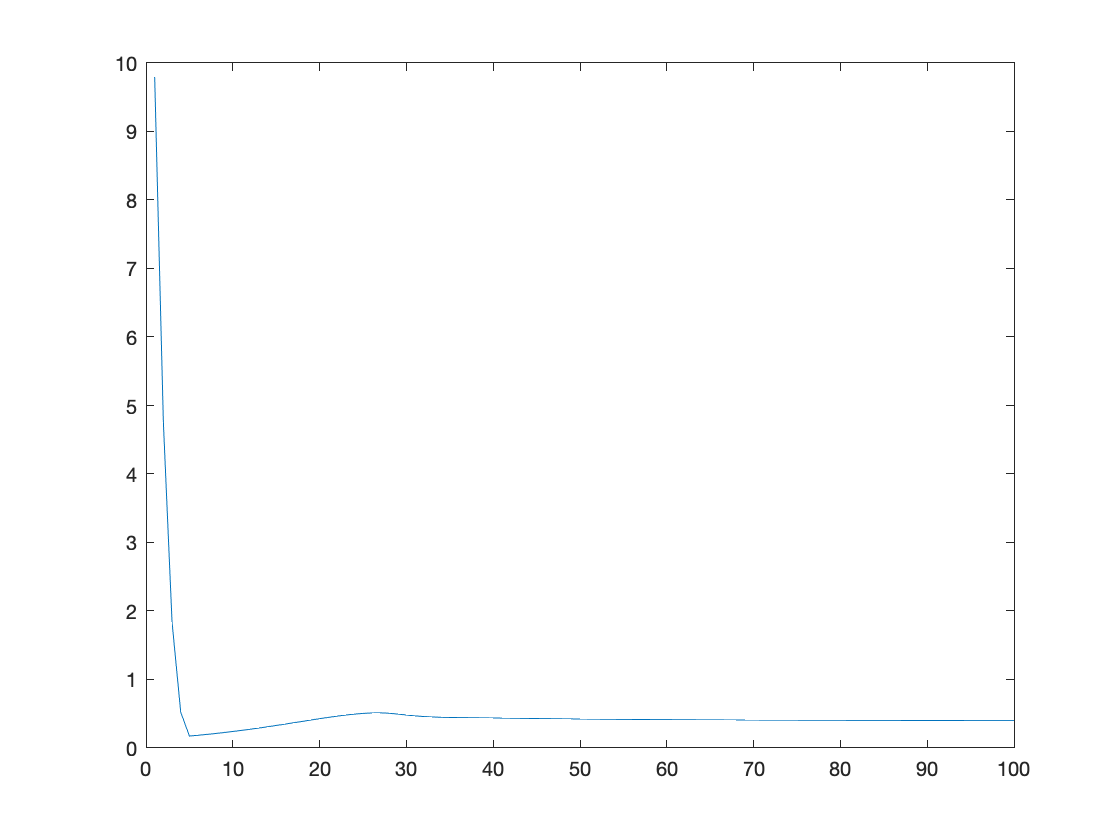

plot(1:Nsimu,U_tot)

# Application into Simulink

Ouvrir et compléter le simulink ('2A_SG8_MPC_simu_MPC_student.slx'). 

You must also compile the following two sections for the Simulink file to be executable.

#### Umax prediction generator

Amaxpred=zeros(Np,Np);
Amaxpred(1:Np-1,2:Np)=eye((Np-1));
Bmaxpred=zeros(Np,1);
Bmaxpred(Np,1)=eye(1);
Cmaxpred=eye(Np);
Dmaxpred=zeros(Np,1);

#### Setpoint generator (corresponding to$Tmin(K+1|k)$ and $Dmin(K+1|k)$)

Arefpred=zeros(2*Np,2*Np);
Arefpred(1:2*(Np-1),3:2*Np)=eye(2*(Np-1));
Brefpred=zeros(2*Np,2);
Brefpred(2*(Np-1)+1:2*Np,:)=eye(2);
Crefpred=Arefpred;
Drefpred=Brefpred;

sysrefpred=ss(Arefpred,Brefpred,Crefpred,Drefpred,Te);

lambda_u = 0.1;
lambda_e = 1;
sim('SG8_MPC_simu_MPC_validation_student')


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1139
    0.0273

uk_tot =
    0.1412




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1953
    0.0533

uk_tot =
    0.2486




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2487
    0.0781

uk_tot =
    0.3268




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2783
    0.1019

uk_tot =
    0.3802




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2878
    0.1249

uk_tot =
    0.4127




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2806
    0.1473

uk_tot =
    0.4280




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2602
    0.1693

uk_tot =
    0.4295




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2296
    0.1911

uk_tot =
    0.4207




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1921
    0.2129

uk_tot =
    0.4050




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1507
    0.2350

uk_tot =
    0.3856




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1086
    0.2576

uk_tot =
    0.3661




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0689
    0.2810

uk_tot =
    0.3499




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0349
    0.3056

uk_tot =
    0.3405




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0100
    0.3317

uk_tot =
    0.3417




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   -0.0022
    0.3612

uk_tot =
    0.3589




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0014
    0.3941

uk_tot =
    0.3955




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0242
    0.4308

uk_tot =
    0.4550




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.0694
    0.4717

uk_tot =
    0.5411




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.1405
    0.5172

uk_tot =
    0.6578




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.2411
    0.5685

uk_tot =
    0.8096




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.3739
    0.6260

uk_tot =
    0.9999




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.5423
    0.6908

uk_tot =
    1.2331




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.7486
    0.7639

uk_tot =
    1.5125




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    0.9953
    0.8463

uk_tot =
    1.8416




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    1.2841
    0.9395

uk_tot =
    2.2236


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    2.4130
    1.2951

uk_tot =
    3.7081




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    2.8766
    1.4437

uk_tot =
    4.3203




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    3.3819
    1.6093

uk_tot =
    4.9913




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    3.9265
    1.7936

uk_tot =
    5.7200


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.0880
    3.0270

uk_tot =
   10.1150




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.7652
    3.3391

uk_tot =
   11.1043




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.4387
    3.6718

uk_tot =
   12.1105




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.0991
    4.0234

uk_tot =
   13.1225




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.7375
    4.3914

uk_tot =
   14.1290




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.2855
    4.7145

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.3711
    4.6289

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.4272
    4.5728

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.4523
    4.5477

uk_tot =
    15




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.4459
    4.5541

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.4090
    4.5910

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.3442
    4.6558

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.2563
    4.7437

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.1524
    4.8476

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
   10.0426
    4.9574

uk_tot =
    15




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.9075
    5.0925

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.7929
    5.2071

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.6971
    5.3029

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.6186
    5.3814

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.5556
    5.4444

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.5065
    5.4935

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4695
    5.5305

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4429
    5.5571

uk_tot =
    15




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4249
    5.5751

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4141
    5.5859

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4138
    5.5862

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4168
    5.5832

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4215
    5.5785

uk_tot =
   15.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.4253
    5.5717

uk_tot =
   14.9971




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.3698
    5.5050

uk_tot =
   14.8748




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.3174
    5.4425

uk_tot =
   14.7599




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.2664
    5.3838

uk_tot =
   14.6502




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.2156
    5.3288

uk_tot =
   14.5444




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.1639
    5.2770

uk_tot =
   14.4410




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    9.1105
    5.2284

uk_tot =
   14.3389


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.8697
    5.0599

uk_tot =
   13.9296




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.8023
    5.0231

uk_tot =
   13.8254




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.7324
    4.9881

uk_tot =
   13.7205


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.5873
    4.9227

uk_tot =
   13.5100




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.5133
    4.8920

uk_tot =
   13.4052




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.4392
    4.8624

uk_tot =
   13.3017


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.2944
    4.8063

uk_tot =
   13.1007


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.0402
    4.7038

uk_tot =
   12.7439




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9884
    4.6798

uk_tot =
   12.6682


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8457
    4.5889

uk_tot =
   12.4346




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8274
    4.5673

uk_tot =
   12.3947


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8132
    4.5054

uk_tot =
   12.3185




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8205
    4.4856

uk_tot =
   12.3061


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8492
    4.4481

uk_tot =
   12.2972




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8681
    4.4304

uk_tot =
   12.2985




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8882
    4.4135

uk_tot =
   12.3017




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9078
    4.3975

uk_tot =
   12.3053




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9255
    4.3823

uk_tot =
   12.3078




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9392
    4.3681

uk_tot =
   12.3073




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9473
    4.3549

uk_tot =
   12.3022




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.9479
    4.3427

uk_tot =
   12.2906


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8407
    4.3060

uk_tot =
   12.1467




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.7789
    4.3003

uk_tot =
   12.0792




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.7139
    4.2963

uk_tot =
   12.0102




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.6590
    4.2942

uk_tot =
   11.9532


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5427
    4.3080

uk_tot =
   11.8507




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5401
    4.3182

uk_tot =
   11.8583




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5482
    4.3317

uk_tot =
   11.8798




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5671
    4.3486

uk_tot =
   11.9157




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5967
    4.3694

uk_tot =
   11.9661




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.6371
    4.3943

uk_tot =
   12.0314




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.6881
    4.4236

uk_tot =
   12.1118




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.7497
    4.4576

uk_tot =
   12.2073




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8216
    4.4965

uk_tot =
   12.3181


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.3135
    4.7559

uk_tot =
   13.0694




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    8.4330
    4.8179

uk_tot =
   13.2509


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9269
    2.0731

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9545
    2.0455

uk_tot =
     8


Minimum found that satisfies the con


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0419
    1.9581

uk_tot =
     8




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0560
    1.9440

uk_tot =
     8


Minimum found that satisfies the con


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0747
    1.9253

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0727
    1.9273

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0420
    1.9580

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.0238
    1.9762

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.9169
    2.0831

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8832
    2.1168

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.8473
    2.1527

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7706
    2.2294

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7306
    2.2694

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6082
    2.3918

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.8636
    4.7281

uk_tot =
   12.5918


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.3372
    4.4923

uk_tot =
   11.8295




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.2259
    4.4419

uk_tot =
   11.6678




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.1242
    4.3954

uk_tot =
   11.5197


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.9512
    4.3141

uk_tot =
   11.2653




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.8798
    4.2791

uk_tot =
   11.1589


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6885
    4.1720

uk_tot =
   10.8605




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6616
    4.1522

uk_tot =
   10.8139


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6203
    4.1061

uk_tot =
   10.7265




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6172
    4.0944

uk_tot =
   10.7116


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6294
    4.0672

uk_tot =
   10.6966




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6384
    4.0603

uk_tot =
   10.6986




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6488
    4.0542

uk_tot =
   10.7030


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6719
    4.0440

uk_tot =
   10.7159




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6836
    4.0398

uk_tot =
   10.7234


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7152
    4.0295

uk_tot =
   10.7447




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7237
    4.0266

uk_tot =
   10.7503


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7410
    4.0192

uk_tot =
   10.7603




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7438
    4.0171

uk_tot =
   10.7609




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7451
    4.0151

uk_tot =
   10.7601


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7434
    4.0114

uk_tot =
   10.7548




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7405
    4.0099

uk_tot =
   10.7505




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7364
    4.0088

uk_tot =
   10.7452




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7309
    4.0081

uk_tot =
   10.7390


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7165
    4.0077

uk_tot =
   10.7242




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7078
    4.0082

uk_tot =
   10.7160




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6984
    4.0093

uk_tot =
   10.7076




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6885
    4.0109

uk_tot =
   10.6994




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6785
    4.0131

uk_tot =
   10.6917




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6689
    4.0161

uk_tot =
   10.6850




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6599
    4.0200

uk_tot =
   10.6799


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6450
    4.0563

uk_tot =
   10.7013




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6520
    4.0682

uk_tot =
   10.7203




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6639
    4.0821

uk_tot =
   10.7459




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6810
    4.0981

uk_tot =
   10.7791


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.8130
    4.1892

uk_tot =
   11.0023




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.8641
    4.2200

uk_tot =
   11.0841




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.9230
    4.2545

uk_tot =
   11.1775




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.9901
    4.2929

uk_tot =
   11.2830




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.0654
    4.3355

uk_tot =
   11.4008




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.1485
    4.3817

uk_tot =
   11.5302




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.2389
    4.4313

uk_tot =
   11.6701




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.3363
    4.4839

uk_tot =
   11.8202




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.4403
    4.5393

uk_tot =
   11.9797


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5048
    2.4952

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5333
    2.4667

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5906
    2.4094

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6185
    2.3815

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6453
    2.3547

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7490
    2.2510

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7613
    2.2387

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7764
    2.2236

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7714
    2.2286

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7629
    2.2371

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7511
    2.2489

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.7362
    2.2638

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6976
    2.3024

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6744
    2.3256

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.6491
    2.3509

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5930
    2.4070

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.5628
    2.4372

uk_tot =
    8.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    5.4679
    2.5321

uk_tot =
    8.0000




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.5318
    4.6604

uk_tot =
   12.1922




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.4153
    4.6068

uk_tot =
   12.0221


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.1962
    4.5060

uk_tot =
   11.7022




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    7.0960
    4.4598

uk_tot =
   11.5558


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.8415
    4.3407

uk_tot =
   11.1822




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.7733
    4.3076

uk_tot =
   11.0809


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5838
    4.2054

uk_tot =
   10.7892




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5556
    4.1865

uk_tot =
   10.7421




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5341
    4.1698

uk_tot =
   10.7039


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5090
    4.1422

uk_tot =
   10.6512




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5041
    4.1309

uk_tot =
   10.6351




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5035
    4.1211

uk_tot =
   10.6246


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5124
    4.1050

uk_tot =
   10.6174




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5208
    4.0984

uk_tot =
   10.6192


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5676
    4.0794

uk_tot =
   10.6469




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5803
    4.0759

uk_tot =
   10.6562




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5928
    4.0728

uk_tot =
   10.6656




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6047
    4.0700

uk_tot =
   10.6747




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6158
    4.0674

uk_tot =
   10.6832




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6258
    4.0650

uk_tot =
   10.6908


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6423
    4.0608

uk_tot =
   10.7031




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6486
    4.0589

uk_tot =
   10.7075


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6593
    4.0536

uk_tot =
   10.7129




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6602
    4.0520

uk_tot =
   10.7122


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6561
    4.0473

uk_tot =
   10.7034




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6527
    4.0458

uk_tot =
   10.6985


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6324
    4.0401

uk_tot =
   10.6725




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6261
    4.0387

uk_tot =
   10.6649


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6063
    4.0348

uk_tot =
   10.6411




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5997
    4.0335

uk_tot =
   10.6332


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5748
    4.0287

uk_tot =
   10.6036




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5693
    4.0276

uk_tot =
   10.5969


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5548
    4.0243

uk_tot =
   10.5791




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5507
    4.0233

uk_tot =
   10.5740




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5471
    4.0223

uk_tot =
   10.5693


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5408
    4.0203

uk_tot =
   10.5611




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5382
    4.0194

uk_tot =
   10.5575




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5359
    4.0185

uk_tot =
   10.5543




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5339
    4.0177

uk_tot =
   10.5515




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5321
    4.0171

uk_tot =
   10.5491


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5294
    4.0164

uk_tot =
   10.5457


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5281
    4.0165

uk_tot =
   10.5447




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5282
    4.0170

uk_tot =
   10.5452


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5319
    4.0197

uk_tot =
   10.5516


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5417
    4.0251

uk_tot =
   10.5667


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5583
    4.0335

uk_tot =
   10.5918


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5831
    4.0462

uk_tot =
   10.6293


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6172
    4.0623

uk_tot =
   10.6795


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.2950
    3.7050

uk_tot =
   10.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.3127
    3.6873

uk_tot =
   10.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.3235
    3.6765

uk_tot =
   10.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.3253
    3.6747

uk_tot =
   10.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.3128
    3.6872

uk_tot =
   10.0000


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6829
    4.0995

uk_tot =
   10.7824


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.6070
    4.0675

uk_tot =
   10.6745


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5488
    4.0433

uk_tot =
   10.5921


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5134
    4.0269

uk_tot =
   10.5404


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.4968
    4.0134

uk_tot =
   10.5102


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5009
    4.0088

uk_tot =
   10.5097


Minimum found that satisfies the


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
uk =
    6.5097
    4.0060

uk_tot =
   10.5157


Minimum found that satisfies the

ans =   Simulink.SimulationOutput:

                   tout: [417x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
